clear; clc; close all;
rng(0);

%% --- PARAMETRI ---
epochs = 50; learning_rate = 0.01; bottleneck = 40;
train_ratio = 0.8;

%% --- SETUP PATH ---
projectRoot = pwd;
addpath(genpath(projectRoot));
this_folder = pwd;
results_path = fullfile(this_folder,'results');
if ~exist(results_path,'dir'), mkdir(results_path); end

%% --- CARICAMENTO DATI ---
load('dataset/volti_dataset.mat');  % A (m×n)
A = double(A)/255;
[m, n] = size(A); img_h = 112; img_w = 92;

%% --- DATASET: X sono le immagini vettorizzate ---
X = A'; % [n x m], ogni riga è un'immagine "flattened"
input_dim = m;

%% --- SPLIT TRAIN/TEST ---
idx = randperm(n);
n_train = round(train_ratio * n);
X_train = X(idx(1:n_train), :);
X_test  = X(idx(n_train+1:end), :);

%% --- TRAIN AUTOENCODER ---
[W_enc, b_enc, W_dec, b_dec, loss_history] = ...
    autoencoder_train(X_train, bottleneck, epochs, learning_rate);

[AE] Epoca 10/50, MSE=0.23320
[AE] Epoca 20/50, MSE=0.23057
[AE] Epoca 30/50, MSE=0.22799
[AE] Epoca 40/50, MSE=0.22543
[AE] Epoca 50/50, MSE=0.22291



%% --- EVALUATION: MSE e COSINE ---
cosine_sim = @(x,y) dot(x,y) / (norm(x)*norm(y)+eps);
mse = @(X1,X2) mean(sum((X1-X2).^2,2));
cosacc = @(X1,X2,thr) mean(arrayfun(@(i) cosine_sim(X1(i,:)',X2(i,:)')>thr, 1:size(X1,1)));

% Ricostruzione train
X_train_rec = zeros(size(X_train));
for i=1:size(X_train,1)
    x = X_train(i,:)';
    h = max(0, W_enc*x + b_enc);
    X_train_rec(i,:) = (W_dec*h + b_dec)';
end
mse_train = mse(X_train, X_train_rec);
cos_train = mean(arrayfun(@(i) cosine_sim(X_train(i,:)', X_train_rec(i,:)'), 1:size(X_train,1)));

% Ricostruzione test
X_test_rec = zeros(size(X_test));
for i=1:size(X_test,1)
    x = X_test(i,:)';
    h = max(0, W_enc*x + b_enc);
    X_test_rec(i,:) = (W_dec*h + b_dec)';
end
mse_test = mse(X_test, X_test_rec);
cos_test = mean(arrayfun(@(i) cosine_sim(X_test(i,:)', X_test_rec(i,:)'), 1:size(X_test,1)));

fprintf('>>> Train MSE loss (autoencoder): %.4f\n', mse_train);

>>> Train MSE loss (autoencoder): 2295.5549


fprintf('>>> Test  MSE loss (autoencoder): %.4f\n', mse_test);

>>> Test  MSE loss (autoencoder): 2244.0972


fprintf('>>> Train mean cosine similarity:  %.4f\n', cos_train);

>>> Train mean cosine similarity:  0.9502


fprintf('>>> Test  mean cosine similarity:  %.4f\n', cos_test);

>>> Test  mean cosine similarity:  0.9505



%% --- Accuracy come % ricostruzioni "buone" (MSE < THR oppure cosine > thr) ---

THR_COS = 0.95; % puoi cambiare questa soglia
cos_acc_train = cosacc(X_train, X_train_rec, THR_COS);
cos_acc_test  = cosacc(X_test,  X_test_rec,  THR_COS);

fprintf('>>> Train cosine similarity_acc (cosine > %.2f): %.2f%%\n', THR_COS, 100*cos_acc_train);

>>> Train cosine similarity_acc (cosine > 0.95): 67.68%


fprintf('>>> Test  cosine similarity_acc (cosine > %.2f): %.2f%%\n', THR_COS, 100*cos_acc_test);

>>> Test  cosine similarity_acc (cosine > 0.95): 67.07%


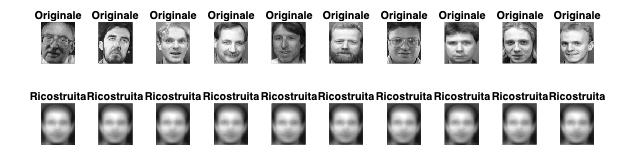


%% --- VISUALIZZAZIONE RICOSTRUZIONI (su test) ---
num_show = 10;
perm = randperm(size(X_test,1), num_show);

figure('Name','Autoencoder: ricostruzioni (test)','NumberTitle','off', 'Position', [100, 100, 120*num_show, 320]);
tiledlayout(2, num_show, 'Padding','compact', 'TileSpacing','compact');
for i = 1:num_show
    x_img = X_test(perm(i), :)';  % [m x 1]
    h = max(0, W_enc * x_img + b_enc);
    x_rec = W_dec * h + b_dec;    % [m x 1]
    orig_idx = idx(n_train+perm(i));

    nexttile(i)
    imshow(reshape(A(:,orig_idx), img_h, img_w), []);
    title('Originale','FontSize',12);

    nexttile(i + num_show)
    imshow(reshape(x_rec, img_h, img_w), []);
    title('Ricostruita','FontSize',12);
end
saveas(gcf, fullfile(results_path,'ae_reconstructions.png'));

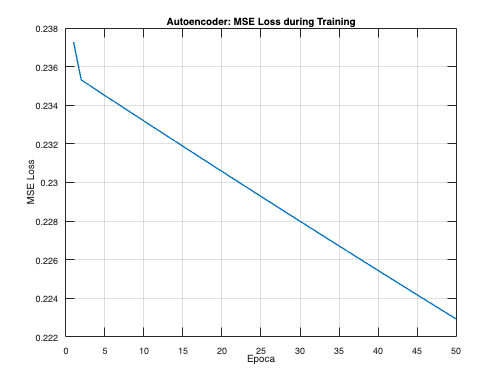


%% --- ANDAMENTO DELLA LOSS ---
figure; plot(1:epochs, loss_history, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('MSE Loss'); title('Autoencoder: MSE Loss during Training');
grid on; saveas(gcf, fullfile(results_path,'ae_loss.png'));